# Loading The Diabetes Data Set

clear
clc
load pimadiabetes.mat

## Starting PCA mathod

Mean = mean(Features)                  % get mean value of each column

Mean =     3.8451  120.8945   69.1055   20.5365   79.7995   31.9926    0.4719   33.2409


NewFeatures = Features - Mean         % Center all values to mean

NewFeatures =     2.1549   27.1055    2.8945   14.4635  -79.7995    1.6074    0.1551   16.7591
   -2.8451  -35.8945   -3.1055    8.4635  -79.7995   -5.3926   -0.1209   -2.2409
    4.1549   62.1055   -5.1055  -20.5365  -79.7995   -8.6926    0.2001   -1.2409
   -2.8451  -31.8945   -3.1055    2.4635   14.2005   -3.8926   -0.3049  -12.2409
   -3.8451   16.1055  -29.1055   14.4635   88.2005   11.1074    1.8161   -0.2409
    1.1549   -4.8945    4.8945  -20.5365  -79.7995   -6.3926   -0.2709   -3.2409
   -0.8451  -42.8945  -19.1055   11.4635    8.2005   -0.9926   -0.2239   -7.2409
    6.1549   -5.8945  -69.1055  -20.5365  -79.7995    3.3074   -0.3379   -4.2409
   -1.8451   76.1055    0.8945   24.4635  463.2005   -1.4926   -0.3139   19.7591
    4.1549    4.1055   26.8945  -20.5365  -79.7995  -31.9926   -0.2399   20.7591


[U,E,Coeff] = svd(NewFeatures)

U =    -0.0236    0.0425   -0.0133   -0.0402   -0.0561   -0.0185   -0.0091   -0.0107    0.0100   -0.0464    0.0034   -0.0566   -0.0665    0.0237   -0.0166   -0.0279    0.0349   -0.0272    0.0247    0.0270    0.0078   -0.0446   -0.0286   -0.0534   -0.0800   -0.0654   -0.0306    0.0335   -0.0999   -0.0096   -0.0237    0.0091    0.0136   -0.0167   -0.0688   -0.0041   -0.0679   -0.0608    0.0153   -0.0153    0.0118   -0.0286   -0.0377   -0.0578   -0.0295    0.0391    0.0345    0.0197   -0.0338   -0.0254
   -0.0256   -0.0342   -0.0100   -0.0231   -0.0118   -0.0298   -0.0333    0.0103    0.0887   -0.0033   -0.0077    0.0471    0.0062    0.0795    0.0466   -0.0356    0.0051   -0.0180   -0.0192   -0.0031    0.0105   -0.0299    0.0835   -0.0061    0.0187   -0.0023    0.0268   -0.0231    0.0146   -0.0033   -0.0187    0.0438   -0.0358   -0.0322   -0.0078   -0.0239    0.0119   -0.0298   -0.0321   -0.0174    0.0694    0.0111   -0.0207    0.0538    0.0378    0.0670    0.0299   -0.0540   -0.0230   -0

E = 	1.0e+03 *

    3.2127         0         0         0         0         0         0         0
         0    0.8458         0         0         0         0         0         0
         0         0    0.5473         0         0         0         0         0
         0         0         0    0.3899         0         0         0         0
         0         0         0         0    0.2940         0         0         0
         0         0         0         0         0    0.1875         0         0
         0         0         0         0         0         0    0.0772         0
         0         0         0         0         0         0         0    0.0089
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


Coeff =    -0.0020    0.0226   -0.0225    0.0490   -0.1516    0.0050    0.9867   -0.0061
    0.0978    0.9722    0.1434   -0.1198    0.0879   -0.0507    0.0009    0.0008
    0.0161    0.1419   -0.9225    0.2627    0.2322   -0.0756   -0.0012   -0.0005
    0.0608   -0.0579   -0.3070   -0.8844   -0.2600   -0.2214   -0.0004    0.0025
    0.9931   -0.0946    0.0210    0.0656    0.0002    0.0061    0.0014    0.0003
    0.0140    0.0470   -0.1324   -0.1928   -0.0215    0.9708   -0.0027    0.0027
    0.0005    0.0008   -0.0006   -0.0027   -0.0016    0.0020   -0.0063   -1.0000
   -0.0036    0.1402   -0.1255    0.3010   -0.9205    0.0151   -0.1626    0.0020


S = NewFeatures*Coeff

S =   -75.7147   35.9508   -7.2608  -15.6693  -16.5065   -3.4604   -0.7020   -0.0950
  -82.3583  -28.9082   -5.4967   -9.0046   -3.4815   -5.5903   -2.5720    0.0915
  -74.6306   67.9065   19.4618    5.6531   10.3001   -7.1444    4.2791   -0.2710
   11.0774  -34.8985   -0.0530   -1.3149    7.6194   -2.5839   -0.8098    0.2733
   89.7438    2.7469   25.2129  -18.9942   -8.5227    9.4870   -3.6264   -1.6743
  -80.9779    3.9469    0.6414   15.1177    8.9770   -2.3147    1.5694    0.1600
    4.3510  -46.9339    9.1834  -11.5094   -4.3715    0.0565    0.3403    0.2182
  -82.1373   -7.0980   67.4890   -6.1312   -8.3369   12.7596    6.7294    0.2582
  468.8664   31.5283   10.0571    5.9896  -17.2557   -7.6639   -4.3103    0.6090
  -80.1938   18.0483  -18.0498   32.1270   -7.1212  -28.9094    0.6787    0.0851


## Extracting the first the 3 principal components


S = [S , diabetesOutput]

S =   -75.7147   35.9508   -7.2608  -15.6693  -16.5065   -3.4604   -0.7020   -0.0950    1.0000
  -82.3583  -28.9082   -5.4967   -9.0046   -3.4815   -5.5903   -2.5720    0.0915         0
  -74.6306   67.9065   19.4618    5.6531   10.3001   -7.1444    4.2791   -0.2710    1.0000
   11.0774  -34.8985   -0.0530   -1.3149    7.6194   -2.5839   -0.8098    0.2733         0
   89.7438    2.7469   25.2129  -18.9942   -8.5227    9.4870   -3.6264   -1.6743    1.0000
  -80.9779    3.9469    0.6414   15.1177    8.9770   -2.3147    1.5694    0.1600         0
    4.3510  -46.9339    9.1834  -11.5094   -4.3715    0.0565    0.3403    0.2182    1.0000
  -82.1373   -7.0980   67.4890   -6.1312   -8.3369   12.7596    6.7294    0.2582         0
  468.8664   31.5283   10.0571    5.9896  -17.2557   -7.6639   -4.3103    0.6090    1.0000
  -80.1938   18.0483  -18.0498   32.1270   -7.1212  -28.9094    0.6787    0.0851    1.0000


SNDiabetic = [];
SDiabetic = [] ;
for i = 1:size(diabetesOutput,1)
    if(S(i,9) ==0 )
        SNDiabetic = [SNDiabetic ; S(i,:)];
    else
        SDiabetic = [SDiabetic ; S(i,:)];
    end
end
SNDiabetic = SNDiabetic(:,[1,2,3])

SNDiabetic =   -82.3583  -28.9082   -5.4967
   11.0774  -34.8985   -0.0530
  -80.9779    3.9469    0.6414
  -82.1373   -7.0980   67.4890
  -81.1050    1.2090  -18.3904
  -78.7164   31.1284   -5.2936
    2.0248  -23.8273   26.8092
  156.3045   -8.7757  -19.8902
  -82.4197   -7.8298  -14.8961
   56.9849  -31.1005    5.0388


SDiabetic = SDiabetic(:,[1,2,3])

SDiabetic =   -75.7147   35.9508   -7.2608
  -74.6306   67.9065   19.4618
   89.7438    2.7469   25.2129
    4.3510  -46.9339    9.1834
  468.8664   31.5283   10.0571
  -80.1938   18.0483  -18.0498
  -75.7422   55.7585    5.8430
  767.4741   -4.2677   30.5673
   98.7574   37.5678    4.8343
  -83.6832  -21.5772   65.7303


Plotting the Principle components onto a 3D Graph

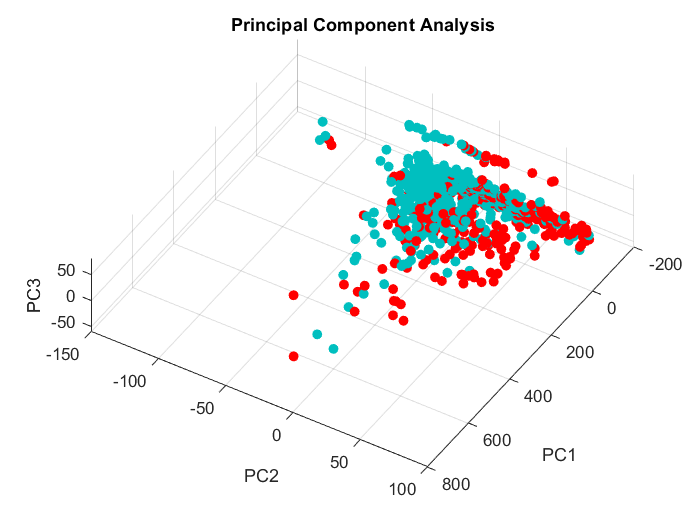


scatter3(SDiabetic(:,1),SDiabetic(:,2),SDiabetic(:,3),'filled' , 'MarkerFaceColor',[1 0 .0])
hold on
scatter3(SNDiabetic(:,1),SNDiabetic(:,2),SNDiabetic(:,3),'filled' ,'MarkerFaceColor',[0 .75 .75])
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
title("Principal Component Analysis")
axis ([-200 800 -150 100 -60 80])